% Simulation of linear system of monocopter with flaps
clc
clear all
close all

load gyro_x_flap.mat
load gyro_y_flap.mat
load gyro_x_flap_quat.mat
load gyro_y_flap_quat.mat
load jerk_scaling_factor_x.mat
load jerk_scaling_factor_y.mat
load error_y.mat

 
% load ka_flap.mat
% load ka_flap_NDI.mat


## Parameters

motor_scaling = 0.135/4;
J = 3.2284E-6*motor_scaling; % moment of inertia of the rotor
b = 3.5077E-6*motor_scaling; % motor viscous friction constant 
K = 0.0274*motor_scaling; % electromotive force constant, motor torque constant 
R = 4*motor_scaling; % electric resistance 
L = 2.75E-6*motor_scaling; % electric inductance  
Jxx = 0.014; % symmetrical so most of it is abt x so therefore Jxx
Jzz = 0.0151724197;
pitch = 41;
pitch = abs(pitch);
plot_variable = 10;
% (bod pitch * ka * motor rpm) contributes to lift force for disk torque
ka = 1; % .01,.03,.05,.07,.09,.11,.13
ka = ka*plot_variable; % x1, x2, x3, x4, x5...all the way to x13, default is x 10
rps = -22.0440;
rps_squared = rps^2;
cl = 0.11;
cd = 0.023; 
g = 9.81;
rho = 1.225;
radius = 0.61;
chord_length = 0.1;
mass = 0.16;
torque_w_mass = radius*((cl*pitch*ka*rps_squared*rho*chord_length*(radius^3))/(6));
drag_rotation = (cd*pitch*ka*rps_squared*rho*chord_length*(radius^3))/(6*mass);
com = 1/((g + drag_rotation)); % omega abt x is positive (pitch) linear acc y, omega abt y is negative (roll) linear acc x
linesize = 3;
Fontsize = 10;

t = 0:0.01:5;
% monocopter precession is like a speed booster lol

u3 = 1/3*sin((2.5*t)-(pi)); % omega abt x, linear acc y
u = sin((2.5*t)-(pi)); % omega abt x, linear acc y
u3 = jerk_scaling_factor_y.*u3; % omega abt x, linear acc y
u = jerk_scaling_factor_y.*u; % omega abt x, linear acc y

% u3 = 1/3*(sin((2.2*t)-(pi/2))); % omega abt y, linear acc x
% u = sin((2.2*t)-(pi/2)); % omega abt y, linear acc x
% u3 = jerk_scaling_factor_x.*u3; % omega abt y, linear acc x
% u = jerk_scaling_factor_x.*u; % omega abt y, linear acc x


%% servo and angular acceleration feedback
omega_dot = torque_w_mass/Jxx;
s = tf('s');
max_rpm = 11600 * 4.2;
min_rpm = max_rpm/2;
hovering_rpm = min_rpm+((max_rpm-min_rpm)*3/4);
remaining_rpm = max_rpm - hovering_rpm %tamp

remaining_rpm = 6090

motor = K/(((J*s+b)*(L*s+R)+K^2)); % sam no integrator at the bottom, unlike the flapped one  
H_motor = 0.001; % for sam, lpf is needed
H_omega_dot_tf = 1; % lpf is needed and tuned here for indi, ndi is better only  
mtf = motor/(1+(motor*H_motor)); % dun use feedback....cos the hs is different n not one
% isstable(mtf)

ans = logical
   1


% pole(mtf)

ans = 1.0e+06 *

   -1.4545
   -1.4544
   -0.0001
   -0.0001


% omega_dot_tf = stf; % ndi
omega_dot = mtf*omega_dot;
% omega_dot_tf = omega_dot/(1+(omega_dot*H_omega_dot_tf)); % indi
% isstable(omega_dot_tf)
% pole(omega_dot_tf)

%[omega_dot_controller,info] = pidtune(omega_dot,'PID');
omega_dot_tf = feedback(omega_dot,1); % implement feedback for tf which is servo to become servo/(1+(servo*H)
% isstable(omega_dot_tf)

ans = logical
   1


% pole(omega_dot_tf)

ans = 1.0e+07 *

  -0.0727 + 2.0103i
  -0.0727 - 2.0103i
  -0.1454 + 0.0000i
  -0.0000 + 0.0000i


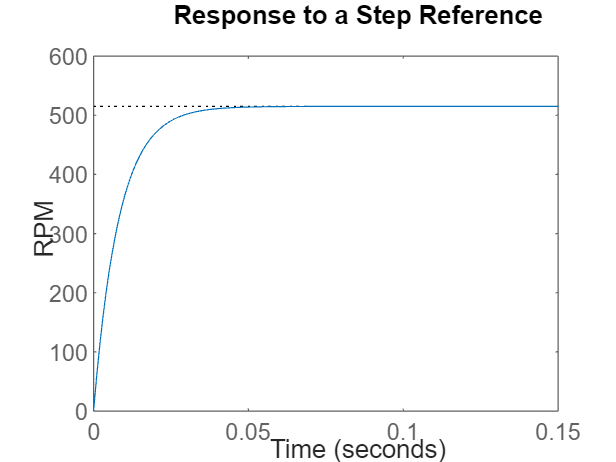


%% to simulate step input of a single motor
% max omega dot = 0.65/2;
t = 0:0.001:0.15;
Config = RespConfig('Amplitude',1);
step(mtf, t, Config) % step function here is in the form of a servo angle 
ylabel('RPM')
title('Response to a Step Reference')

%legend('Kp = 1',  'Kp = 11',  'Kp = 21')


%% to simulate disturbance step input


